讀取資料

data = readtable('cbb.csv');

去除不必要的 column

data.POSTSEASON = categorical(data.POSTSEASON);
data.CONF = categorical(data.CONF);
data = removevars(data, {'TEAM', 'POSTSEASON', 'CONF'});

主成分分析

unique(data.SEED);
data.SEED = str2double(data.SEED);
data = rmmissing(data);
[coeff, score, latent, tsquared, explained] = pca(table2array(data));

顯示結果

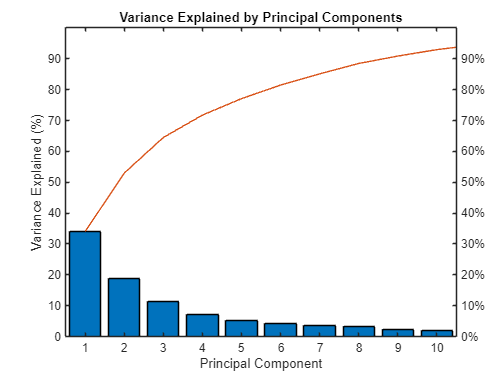

figure;
pareto(explained);
xlabel('Principal Component');
ylabel('Variance Explained (%)');
title('Variance Explained by Principal Components');

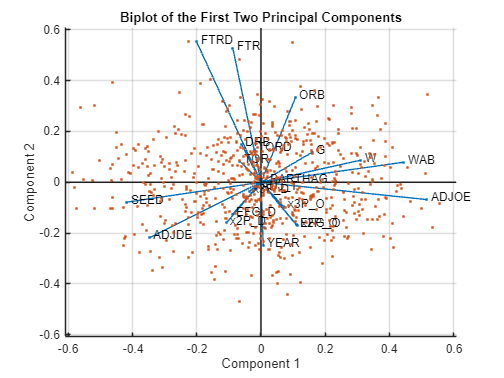


figure;
biplot(coeff(:,1:2), 'Scores', score(:,1:2), 'VarLabels', data.Properties.VariableNames);
title('Biplot of the First Two Principal Components');

K means 群集分析

numClusters = 4;
[idx, C] = kmeans(score(:,1:numClusters), numClusters);
clusteredData = addvars(data, idx, 'NewVariableNames', 'Cluster');

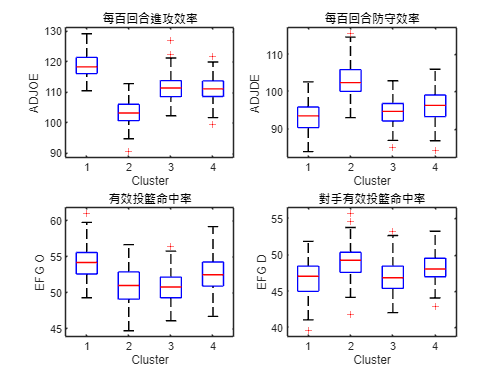

figure;
subplot(2,2,1);
boxplot(clusteredData.ADJOE, clusteredData.Cluster);
xlabel('Cluster');
ylabel('ADJOE');
title('每百回合進攻效率');

subplot(2,2,2);
boxplot(clusteredData.ADJDE, clusteredData.Cluster);
xlabel('Cluster');
ylabel('ADJDE');
title('每百回合防守效率');

subplot(2,2,3);
boxplot(clusteredData.EFG_O, clusteredData.Cluster);
xlabel('Cluster');
ylabel('EFG O');
title('有效投籃命中率');

subplot(2,2,4);
boxplot(clusteredData.EFG_D, clusteredData.Cluster);
xlabel('Cluster');
ylabel('EFG D');
title('對手有效投籃命中率');

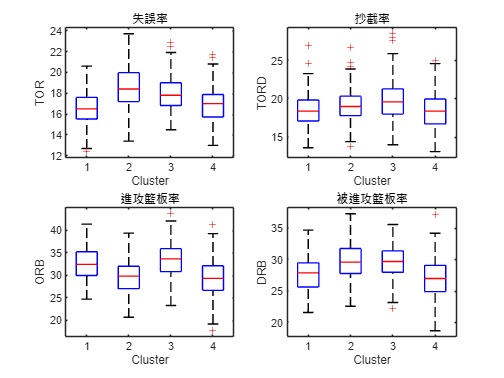

figure;
subplot(2,2,1);
boxplot(clusteredData.TOR, clusteredData.Cluster);
xlabel('Cluster');
ylabel('TOR');
title('失誤率');

subplot(2,2,2);
boxplot(clusteredData.TORD, clusteredData.Cluster);
xlabel('Cluster');
ylabel('TORD');
title('抄截率');

subplot(2,2,3);
boxplot(clusteredData.ORB, clusteredData.Cluster);
xlabel('Cluster');
ylabel('ORB');
title('進攻籃板率');

subplot(2,2,4);
boxplot(clusteredData.DRB, clusteredData.Cluster);
xlabel('Cluster');
ylabel('DRB');
title('被進攻籃板率');

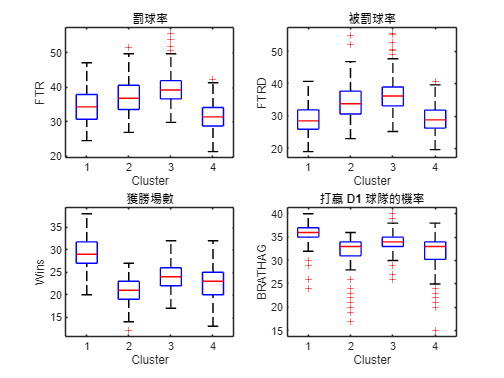

figure;
subplot(2,2,1);
boxplot(clusteredData.FTR, clusteredData.Cluster);
xlabel('Cluster');
ylabel('FTR');
title('罰球率');

subplot(2,2,2);
boxplot(clusteredData.FTRD, clusteredData.Cluster);
xlabel('Cluster');
ylabel('FTRD');
title('被罰球率');

subplot(2,2,3);
boxplot(clusteredData.W, clusteredData.Cluster);
xlabel('Cluster');
ylabel('Wins');
title('獲勝場數');

subplot(2,2,4);
boxplot(clusteredData.G, clusteredData.Cluster);
xlabel('Cluster');
ylabel('BRATHAG');
title('打贏 D1 球隊的機率');